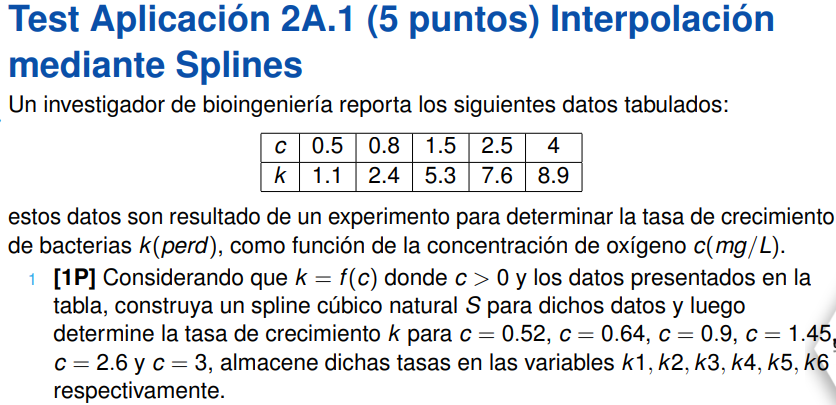

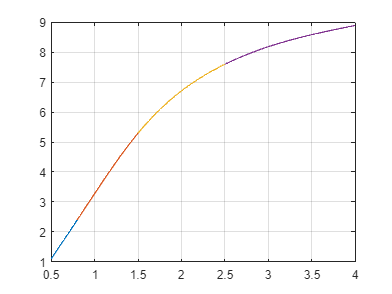

format long
c_val=[0.5 0.8 1.5 2.5 4];
k_val=[1.1 2.4 5.3 7.6 8.9];

cTarget = [0.52 0.64 0.9 1.45 2.6 3];
resultados = zeros(size(cTarget));
S = splinenatural(c_val,k_val);


for i = 1:length(cTarget)
    indice= buscarC(cTarget(i), c_val);
    resultados(i)=reemplazar_splin_natural(cTarget(i), S(indice,:),c_val(indice));
end

k1=resultados(1)

k1 =    1.186181715360030


k2=resultados(2)

k2 =    1.703999434480165


k3=resultados(3)

k3 =    2.839803998756863


k4=resultados(4)

k4 =    5.121624451811181


k5=resultados(5)

k5 =    7.736970844143636


k6=resultados(6)

k6 =    8.188210727043215


k_val=[1.1 2.4 5.3 7.6 8.9];
c_val=[0.5 0.8 1.5 2.5 4];
kTarget = 5;
c0 = 1;
Tol = 0.0001;
S = splinenatural(c_val,k_val);


indiceK = buscarK(kTarget, k_val);
syms c
polinomio = subs(polinomio_cubico(S(indiceK,:),c_val(indiceK)),c)

$$polinomio = \frac{4933744012374823\,c}{1125899906842624}+\frac{5038\,{\left(c-\frac{4}{5}\right)}^{2}}{20685}-\frac{24212\,{\left(c-\frac{4}{5}\right)}^{3}}{28959}-\frac{1556044291846951}{1407374883553280}$$


f = matlabFunction(polinomio-kTarget)

f = function_handle with value:
    @(c)c.*4.382044960116025+(c-4.0./5.0).^2.*2.435581339134639e-1-(c-4.0./5.0).^3.*8.360785938740979e-1-6.10563596809282



resultados_newton = newton(f,c0,Tol)

resultados_newton =    1.000000000000000
   1.392893990544372
   1.416790567322398
   1.416984098578507
   1.416984111676849



c5 = resultados_newton(end)

c5 =    1.416984111676849


function S=splinenatural(X,Y)
N=length(X)-1;
H=diff(X);
E=diff(Y)./H;
diagprinc=2*(H(1:N-1)+H(2:N));
diagsupinf=H(2:N-1);
g0=0; gn=0;
A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
b=6*diff(E');
g=A\b;
g=[g0 g' gn ];
for i=1:N
    S(i,1)=(g(i+1)-g(i))/(6*H(i));
    S(i,2)=g(i)/2;
    S(i,3)=E(i)-H(i)*(g(i+1)+2*g(i))/6;
    S(i,4)=Y(i);
    xx=linspace(X(i),X(i+1),100);
    yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
    plot(xx,yy)
    hold on
end
grid on
hold off
end

function indice = buscarC( valor_c, vector_c )
indice = 1;
i=1;
    while(vector_c(i)<=valor_c)
        indice = i;
        i = i+1;
    end
end

function indice = buscarK( valor_k, vector_k )
indice = 1;
i=1;
    while(vector_k(i)<=valor_k)
        indice = i;
        i = i+1;
    end
end

function valor_k = reemplazar_splin_natural(valor_c, coeficientes,limite_inferior)
    n = length(coeficientes)-1;
    syms x
    poly = 0;

    for i = 1:n+1
        poly = coeficientes(i)*(x-limite_inferior)^(n+1-i)+poly;
    end
    
    valor_k = double(   subs(poly,valor_c) );
    
    end
    
    function poly = polinomio_cubico(coef,xk)
    n = max(size(coef))-1;
    syms x
    poly=0;
    for i= 1:n+1
        poly = coef(i)*(x-xk)^(n+1-i)+poly;
    end
end

function z=newton(f,x0,Tol)
syms x
df=diff(f(x));
dfu=matlabFunction(df);
z=x0;
error=1;
while error>Tol
    x1=x0-f(x0)/dfu(x0);
    z=[z;x1];
    error=abs(x1-x0)/abs(x1);
    x0=x1;
end
end
